imread('frame.png');
boxImage = rgb2gray(I)

boxImage = 156×172 uint8 matrix
   163   163   163   163   163   163   163   163   163   162   162   162   162   162   162   162   162   162   162   162   162   162   162   162   162   162   162   161   160   160   160   160   160   160   160   160   161   161   161   160   160   160   159   159   159   159   159   161   162   161
   163   163   163   163   162   162   162   162   162   162   162   162   163   163   163   162   162   162   162   162   162   162   162   162   162   162   162   161   160   159   159   159   159   160   160   160   160   160   160   160   160   160   159   159   159   159   160   160   161   161
   162   162   162   163   162   162   162   162   162   163   163   163   163   163   163   162   162   162   162   162   162   162   162   162   162   162   161   161   160   159   159   159   159   160   160   160   160   160   160   160   160   159   159   159   159   159   159   159   160   160
   162   162   162   163   162   162   162   162   162   162   16

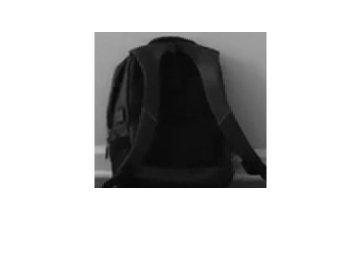

imshow(boxImage);

boxPoints = detectSURFFeatures(boxImage);


I1 = imread('Frame0.jpg');
sceneImage = rgb2gray(I1)

sceneImage = 480×848 uint8 matrix
   221   222   222   222   221   221   221   222   221   221   220   220   220   220   220   220   220   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   218   218   217   216   216   216   216   215   216   216   216   216   215   215   215   215   215
   222   222   222   222   221   221   221   221   221   221   220   220   220   220   220   220   220   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   218   218   217   217   216   216   216   216   215   216   216   216   216   216   215   215   215   215
   222   222   222   222   221   221   221   221   221   221   220   220   220   220   220   220   220   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   217   217   217   216   216   216   216   216   216   216   216   216   216   216   215   215   215   215
   222   222   222   222   222   221   221   221   221   221   

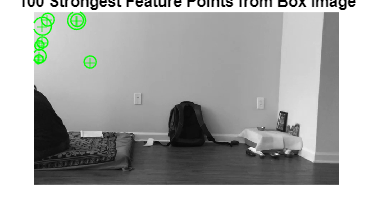

imshow(sceneImage);
scenePoints = detectSURFFeatures(sceneImage);

title('100 Strongest Feature Points from Box Image');
hold on;
plot(selectStrongest(boxPoints, 100));

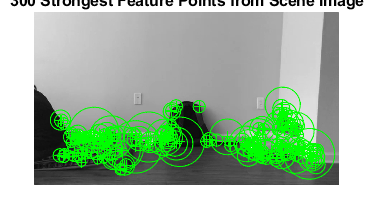


figure;
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

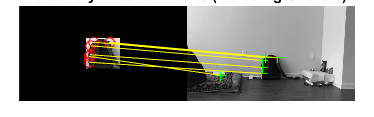

[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);
boxPairs = matchFeatures(boxFeatures, sceneFeatures);
matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);
figure;
showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

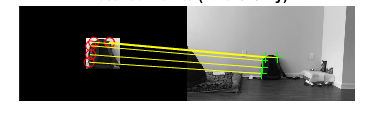

[tform, inlierIdx] = ...
    estimateGeometricTransform2D(matchedBoxPoints, matchedScenePoints, 'affine');
inlierBoxPoints   = matchedBoxPoints(inlierIdx, :);
inlierScenePoints = matchedScenePoints(inlierIdx, :);
figure;
showMatchedFeatures(boxImage, sceneImage, inlierBoxPoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

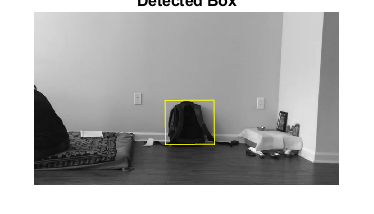

boxPolygon = [1, 1;...                           % top-left
        size(boxImage, 2), 1;...                 % top-right
        size(boxImage, 2), size(boxImage, 1);... % bottom-right
        1, size(boxImage, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon
newBoxPolygon = transformPointsForward(tform, boxPolygon);
figure;
imshow(sceneImage);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), 'Color', 'y');
title('Detected Box');